# SMSM Model - Power Step

Single Machine to Single Machine Model with finite grid inertia and integral grid-side demand balancing. The mechanical input steps from 1.0 to 1.2 pu after 5 s; both voltage references remain at 1.0 pu. Run all sections from the top.

### Constants

% Completed from SM_SM Model WIP 17_08.mlx using report Section 3.2.1.
% Retains the original six machine ODEs and four PCC power-balance constraints.
% Adds PL2 as state 11, so the original first ten state indices are unchanged.
% Pm1 steps 1.0 -> 1.2 pu at 5 s, exactly as in SMIB_P_step.m.
% Voltage references remain fixed; PL2 adjusts through dPL2/dt = KI*domega2.
% The grid equivalent is NOT a literal second generator or a validated
% aggregate grid model. KI models aggregate balancing, not grid strength.
% Requires MATLAB with ode15s; no fsolve or additional toolbox is required.
clear; clc;

% Machine 1 / generator
D1  = 0.1;
H1  = 3;
Xd1 = 0.1;
XT1 = 0.05;
X1 = Xd1 + XT1;

% Machine 2 / finite grid
D2 = 4*D1;
H2 = 4*H1;
Xd2 = 0.05;
XT2 = 0.05;
X2 = Xd2 + XT2;

% Network
XL = 0.3;
XTot = X1 + XL + X2;
f = 50;
ws = 2*pi*f;

### Design Parameters

K1 = 1.2;
K2 = 4*K1;
KI = 0.5;                     % Report choice, NOT a short-circuit-strength gain
KI_crit = ws*D2^2/(8*H2);      % Approximation treating P12 as an external input
% The complete coupled system need not be critically damped at this KI.

### Specified Inputs

Pm1_init  = 0.9;
Pm1_after = 1.1;
tstep = 5;
tend = 30;
dt = 0.01;
Pm1_step = @(t) Pm1_init + (Pm1_after-Pm1_init).*(t >= tstep);
V1o = 1.0;
V2o = 1.0;

s1 = Pm1_init*XL/(V1o*V2o);
s2 = Pm1_after*XL/(V1o*V2o);
if abs(s1) >= 1 || abs(s2) >= 1
    error('A requested operating point is at or beyond the PCC transfer limit.');
end

### Initial Conditions

domega10 = 0;
domega20 = 0;
V1PCCmag0 = V1o;
V2PCCmag0 = V2o;
delta2PCC0 = 0;                % Initial reference only; NOT fixed during simulation

delta1PCC0 = asin(Pm1_init*XL/(V1PCCmag0*V2PCCmag0));
Q12 = (V1PCCmag0^2-V1PCCmag0*V2PCCmag0*cos(delta1PCC0-delta2PCC0))/XL;
Q21 = (V2PCCmag0^2-V2PCCmag0*V1PCCmag0*cos(delta2PCC0-delta1PCC0))/XL;

E10 = hypot(Pm1_init*X1/V1PCCmag0,V1PCCmag0+Q12*X1/V1PCCmag0);
delta10 = delta1PCC0 + atan2(Pm1_init*X1/V1PCCmag0, ...
    V1PCCmag0+Q12*X1/V1PCCmag0);
% Machine 2 has negative electrical injection (absorbs power from Machine 1).
E20 = hypot(-Pm1_init*X2/V2PCCmag0,V2PCCmag0+Q21*X2/V2PCCmag0);
delta20 = delta2PCC0 + atan2(-Pm1_init*X2/V2PCCmag0, ...
    V2PCCmag0+Q21*X2/V2PCCmag0);
PL20 = (E10*E20/XTot)*sin(delta10-delta20);

x0 = [delta10; domega10; E10; delta20; domega20; E20; ...
    V1PCCmag0; delta1PCC0; V2PCCmag0; delta2PCC0; PL20];

### State Space Equations and Solve

% x = [delta1; domega1; E1; delta2; domega2; E2;
%      V1PCCmag; delta1PCC; V2PCCmag; delta2PCC; PL2]
% Seven differential states: 1:6 and 11. Four algebraic variables: 7:10.
% Both internal angles and PCC angles use the same synchronous reference frame.
% The pure series-reactance network has no additional loads at either PCC.
DynamicsEqs = @(t,x,Pm1_value) [ ...
    x(2); ...
    (ws/(2*H1))*(Pm1_value-(x(3)*x(6)/XTot)*sin(x(1)-x(4))-D1*x(2)); ...
    K1*(V1o-x(7)); ...
    x(5); ...
    (ws/(2*H2))*((x(3)*x(6)/XTot)*sin(x(1)-x(4))-x(11)-D2*x(5)); ...
    K2*(V2o-x(9)); ...
    (x(3)*x(7)/X1)*sin(x(1)-x(8))-(x(7)*x(9)/XL)*sin(x(8)-x(10)); ...
    ((x(3)*x(7)*cos(x(1)-x(8))-x(7)^2)/X1 ...
        -(x(7)^2-x(7)*x(9)*cos(x(8)-x(10)))/XL); ...
    (x(6)*x(9)/X2)*sin(x(4)-x(10))-(x(9)*x(7)/XL)*sin(x(10)-x(8)); ...
    ((x(6)*x(9)*cos(x(4)-x(10))-x(9)^2)/X2 ...
        -(x(9)^2-x(9)*x(7)*cos(x(10)-x(8)))/XL); ...
    KI*x(5)];

r0 = DynamicsEqs(0,x0,Pm1_init);
assert(norm(r0,inf) < 1e-9, 'Initial point is not a consistent equilibrium.');
Mass = diag([1 1 1 1 1 1 0 0 0 0 1]);
options = odeset('Mass',Mass,'MassSingular','yes', ...
    'MStateDependence','none','RelTol',1e-8,'AbsTol',1e-10,'MaxStep',0.02);
[tpre,xpre] = ode15s(@(t,x) DynamicsEqs(t,x,Pm1_init), ...
    linspace(0,tstep,round(tstep/dt)+1),x0,options);
[tpost,xpost] = ode15s(@(t,x) DynamicsEqs(t,x,Pm1_after), ...
    linspace(tstep,tend,round((tend-tstep)/dt)+1),xpre(end,:).',options);
t = [tpre; tpost(2:end)];
x = [xpre; xpost(2:end,:)];

### Calculating PG and QG at each point in time

% Positive PG is exported at PCC1 towards PCC2.
delta1 = x(:,1);
domega1 = x(:,2);
E1 = x(:,3);
delta2 = x(:,4);
domega2 = x(:,5);
E2 = x(:,6);
V1PCCmag = x(:,7);
delta1PCC = x(:,8);
V2PCCmag = x(:,9);
delta2PCC = x(:,10);
PL2 = x(:,11);
PG = zeros(length(t),1);
QG = zeros(length(t),1);
for n = 1:length(t)
    PG(n) = V1PCCmag(n)*V2PCCmag(n)/XL*sin(delta1PCC(n)-delta2PCC(n));
    QG(n) = V1PCCmag(n)^2/XL ...
        -V1PCCmag(n)*V2PCCmag(n)/XL*cos(delta1PCC(n)-delta2PCC(n));
end
P12_internal = E1.*E2/XTot.*sin(delta1-delta2);
Pm1_trace = Pm1_step(t);
df1 = domega1/(2*pi);
df2 = domega2/(2*pi);
delta12 = delta1-delta2;
Paccelerating1 = Pm1_trace-P12_internal-D1*domega1;
Paccelerating2 = P12_internal-PL2-D2*domega2;
RoCoF1 = (ws/(2*H1))*Paccelerating1/(2*pi);
RoCoF2 = (ws/(2*H2))*Paccelerating2/(2*pi);
Q2_to_line = V2PCCmag.^2/XL ...
    -V1PCCmag.*V2PCCmag/XL.*cos(delta1PCC-delta2PCC);
Iline = (V1PCCmag.*exp(1i*delta1PCC)-V2PCCmag.*exp(1i*delta2PCC))/(1i*XL);

### Plot

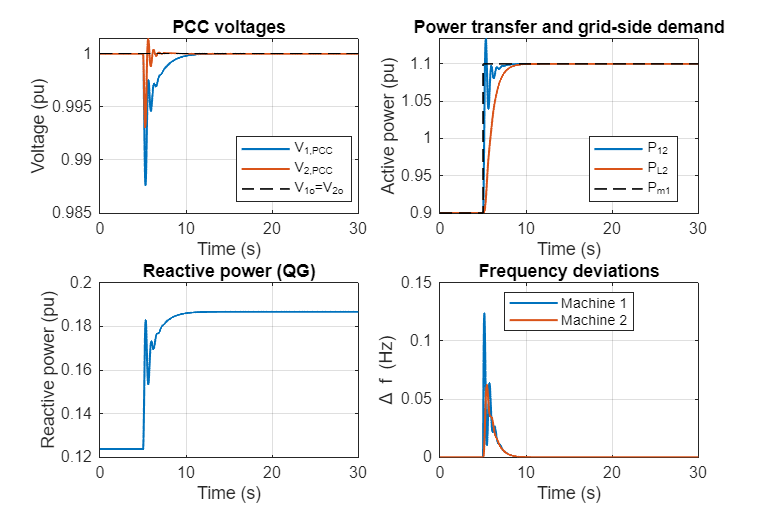

fig = figure('Color','w','Units','inches','Position',[1 1 7.2 4.8]);
subplot(2,2,1);
plot(t,V1PCCmag,'Linewidth',1.3); hold on;
plot(t,V2PCCmag,'Linewidth',1.3);
plot(t,V1o*ones(size(t)),'k--','LineWidth',1);
xlabel('Time (s)'); ylabel('Voltage (pu)');
legend('V_{1,PCC}','V_{2,PCC}','V_{1o}=V_{2o}','Location','best');
title('PCC voltages'); grid on; xlim([0 tend]);

subplot(2,2,2);
plot(t,PG,'Linewidth',1.3); hold on;
plot(t,PL2,'Linewidth',1.3);
stairs(t,Pm1_trace,'k--','Linewidth',1);
xlabel('Time (s)'); ylabel('Active power (pu)');
legend('P_{12}','P_{L2}','P_{m1}','Location','best');
title('Power transfer and grid-side demand'); grid on; xlim([0 tend]);

subplot(2,2,3);
plot(t,QG,'Linewidth',1.3);
xlabel('Time (s)'); ylabel('Reactive power (pu)');
title('Reactive power (QG)'); grid on; xlim([0 tend]);

subplot(2,2,4);
plot(t,df1,'Linewidth',1.3); hold on;
plot(t,df2,'Linewidth',1.3);
xlabel('Time (s)'); ylabel('\Delta f (Hz)');
legend('Machine 1','Machine 2','Location','best');
title('Frequency deviations'); grid on; xlim([0 tend]);
set(findall(fig,'Type','axes'),'FontSize',10);